#### Maciej Górnik

gr 1b, 402325

EAIiIB, AiR

# **Ćw. 3. Identyfikacja obiektu regulacji**

%1
load('pomiary_3out.mat')

%2
size(pomiary_3out)

ans =    300     3


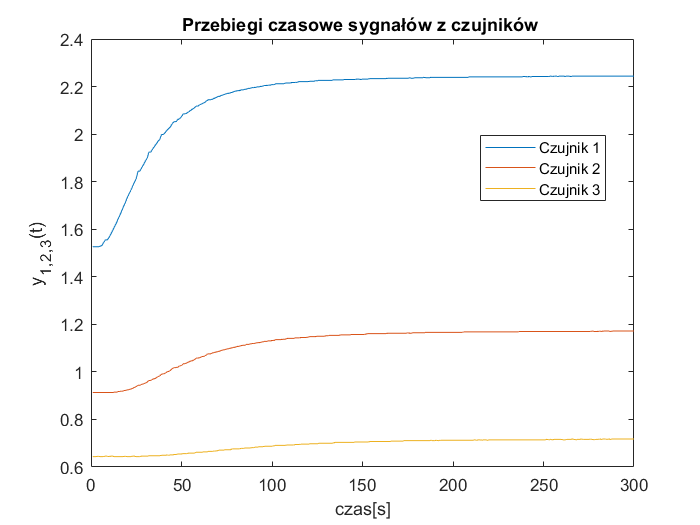

czas=1:1:300;
plot(czas,pomiary_3out)
title("Przebiegi czasowe sygnałów z czujników ")
xlabel("czas[s]")
ylabel("y_1_,_2_,_3(t)")
legend("Czujnik 1","Czujnik 2", "Czujnik 3",'Location',"best")

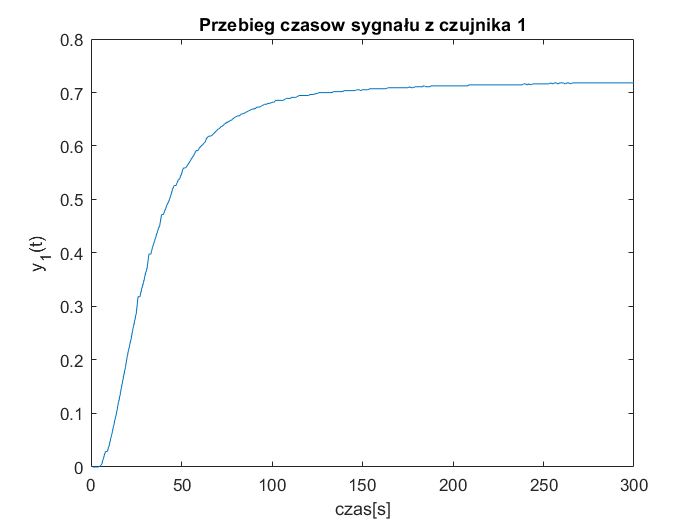


%3
y1=pomiary_3out(:,1) - pomiary_3out(1,1);
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
y3=pomiary_3out(:,3) - pomiary_3out(1,3);

%4
plot(czas,y1)
title("Przebieg czasow sygnału z czujnika 1")
xlabel("czas[s]")
ylabel("y_1(t)")

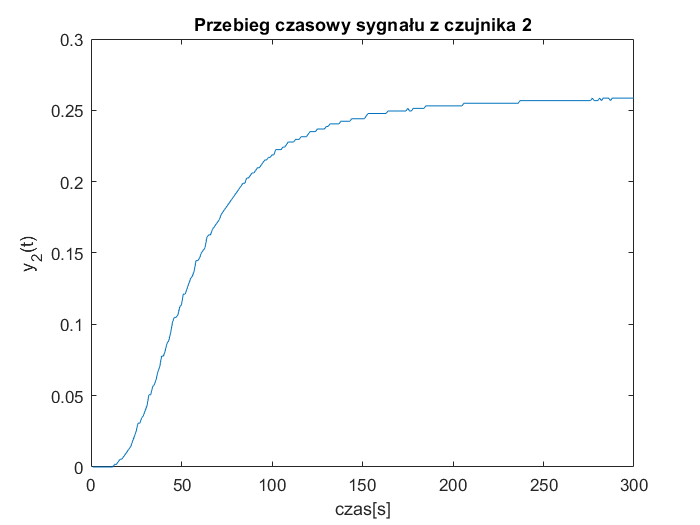



plot(czas,y2)
title("Przebieg czasowy sygnału z czujnika 2")
xlabel("czas[s]")
ylabel("y_2(t)")

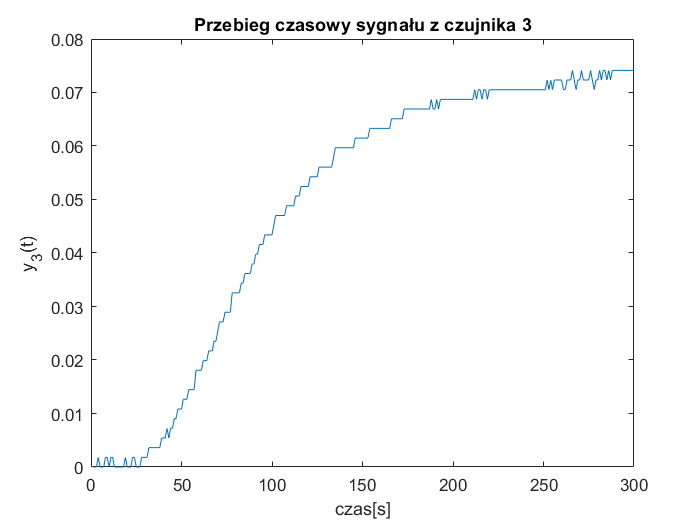


plot(czas,y3)
title("Przebieg czasowy sygnału z czujnika 3")
xlabel("czas[s]")
ylabel("y_3(t)")



% Współczynnik k dla każdego Modelu
k1=y1(300,1)-y1(1,1)/1.0;
k2=y2(300,1)-y2(1,1)/1.0;
k3=y3(300,1)-y3(1,1)/1.0;


## Metoda Kupfmullera I rzędu

### Czujnik 1

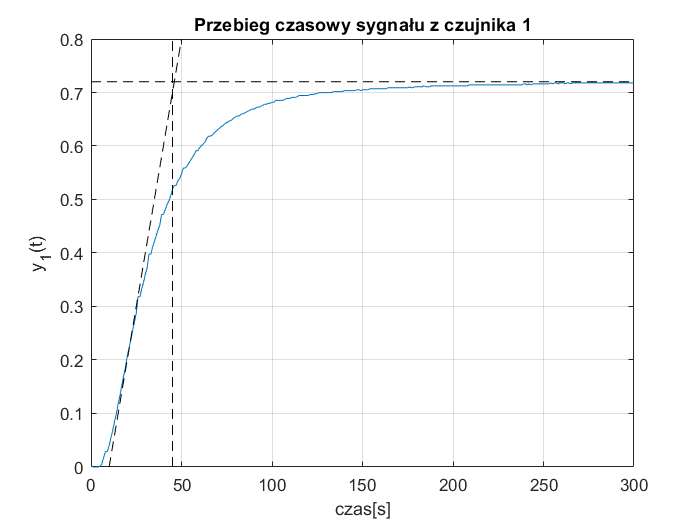

%Metoda Kupfmullera
plot(czas,y1)
title("Przebieg czasowy sygnału z czujnika 1")
xlabel("czas[s]")
ylabel("y_1(t)")
grid

%Wyznaczanie parametrów
line([10 50],[0 0.8],'Color','black','LineStyle','--')
line([0 300],[0.72 0.72],'Color','black','LineStyle','--')
line([45 45],[0 0.8],'Color','black','LineStyle','--')

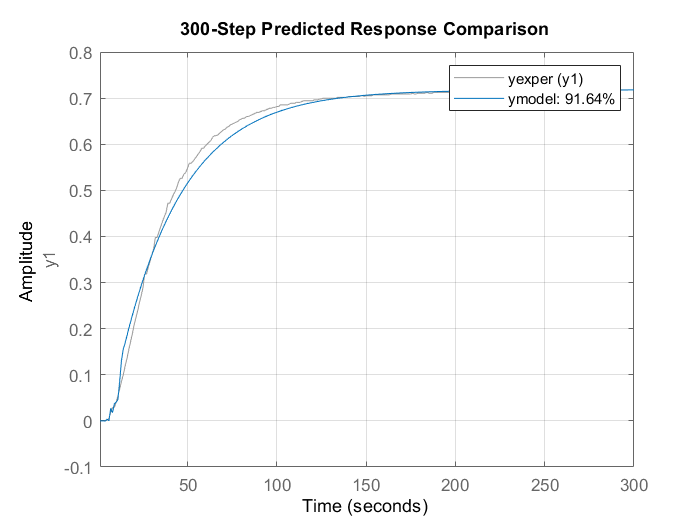


tau = 10;
T = 45-tau;

wej = [T, tau, 1];
kup1rz(wej);

### Czujnik 2

plot(czas,y2)
title("Przebieg czasowy sygnału z czujnika 2")
xlabel("czas[s]")
ylabel("y_2(t)")

k = max(y2)

k = 0.2586

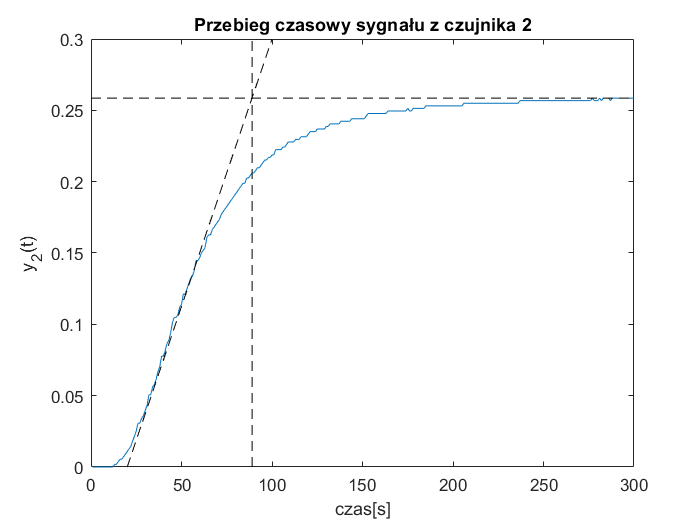


line([20 100],[0 0.3],'Color','black','LineStyle','--')
line([0 300],[k k],'Color','black','LineStyle','--')
line([89 89],[0 0.3],'Color','black','LineStyle','--')

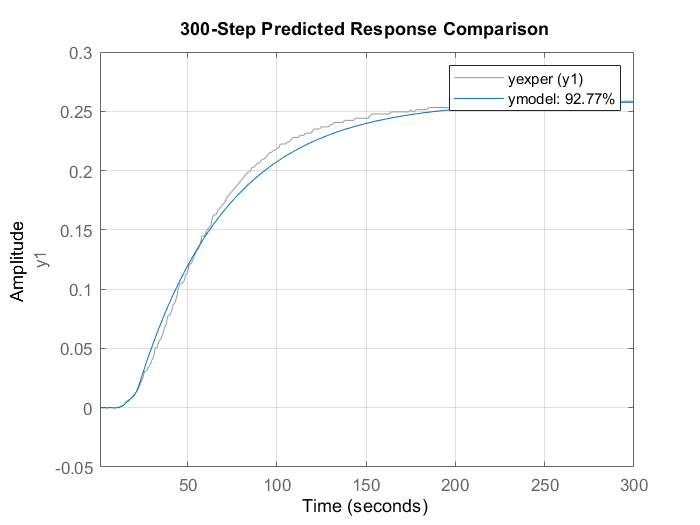


tau = 20;
T = 50;

wej = [T tau 2];
kup1rz(wej);

### **Czujnik 3**

plot(czas,y3)
title("Przebieg czasowy sygnału z czujnika 3")
xlabel("czas[s]")
ylabel("y_3(t)")

k = max(y3)

k = 0.0741

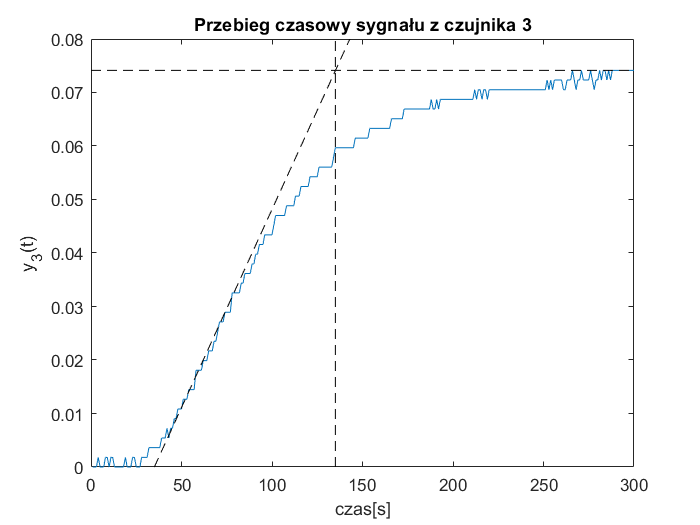

line([35 143],[0 0.08],'Color','black','LineStyle','--')
line([0 300],[k k],'Color','black','LineStyle','--')
line([135 135],[0 0.08],'Color','black','LineStyle','--')

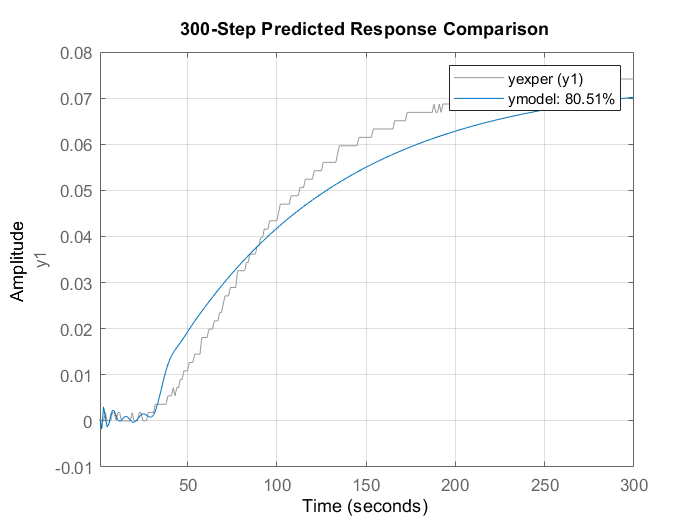


tau = 35;
T = 95;
wej = [T tau 3];
kup1rz(wej);

## Metoda Kupfmullera II rzędu

### Czujnik 1

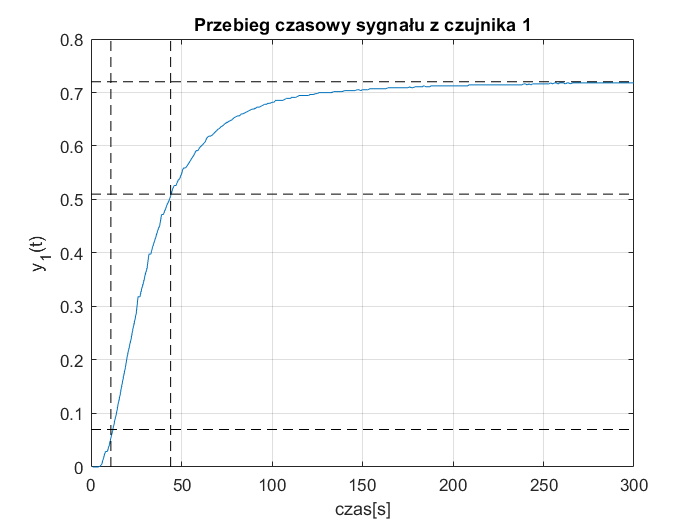

plot(czas,y1)
title("Przebieg czasowy sygnału z czujnika 1")
xlabel("czas[s]")
ylabel("y_1(t)")
grid

line([0 300],[0.72 0.72],'Color','black','LineStyle','--')
line([0 300],[0.51 0.51],'Color','black','LineStyle','--')
line([44 44],[0 0.8],'Color','black','LineStyle','--')
line([11 11],[0 0.8],'Color','black','LineStyle','--')
line([0 300],[0.07 0.07],'Color','black','LineStyle','--')


k = 0.72;
temp = 0.714*k;
tau = 10;
T = 44;
T1 = T/2.4

T1 = 18.3333

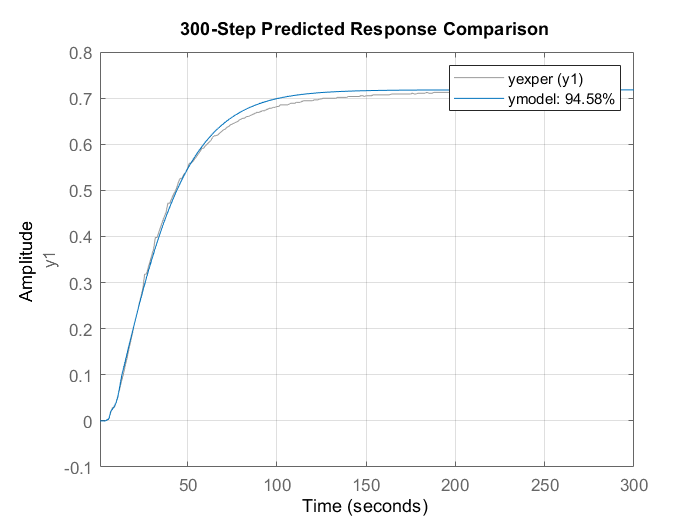

T2 = T1;
wej = [T1 T2 tau 1];
kup2rz(wej);

### Czujnik 2

plot(czas,y2)
title("Przebieg czasowy sygnału z czujnika 2")
xlabel("czas[s]")
ylabel("y_2(t)")
grid

k = max(y2)

k = 0.2586

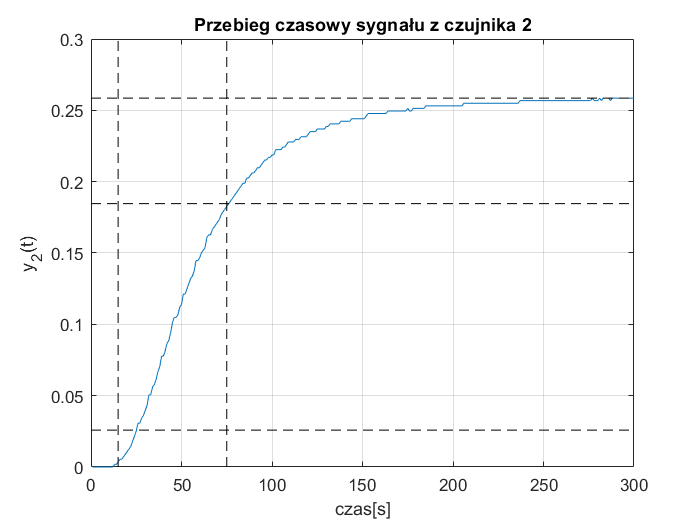


line([0 300],[k k],'Color','black','LineStyle','--')
line([0 300],[0.714*k 0.714*k],'Color','black','LineStyle','--')
line([75 75],[0 0.3],'Color','black','LineStyle','--')
line([15 15],[0 0.3],'Color','black','LineStyle','--')
line([0 300],[0.1*k 0.1*k],'Color','black','LineStyle','--')


tau = 15;
T = 75;
T1 = T/2.4

T1 = 31.2500

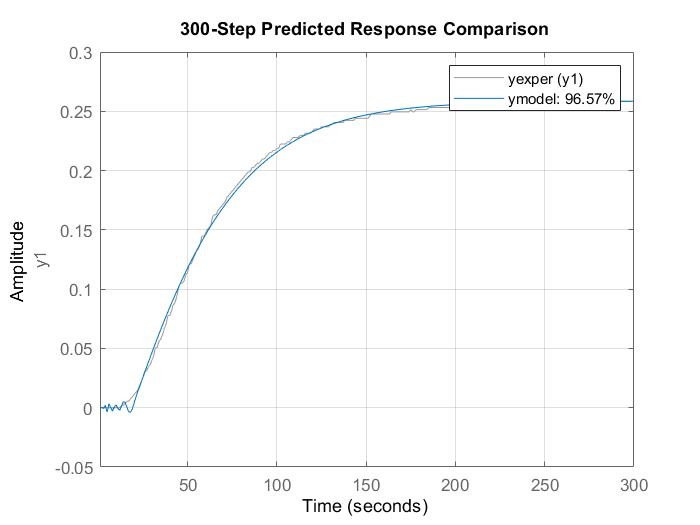

T2 = T1;

wej = [T1 T2 tau 2];
kup2rz(wej);

### **Czujnik 3**

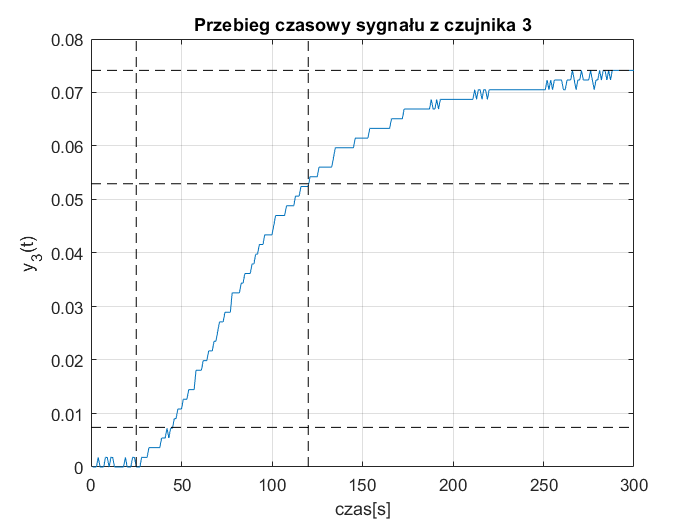

plot(czas,y3)
title("Przebieg czasowy sygnału z czujnika 3")
xlabel("czas[s]")
ylabel("y_3(t)")
grid

k = max(y3);

line([0 300],[k k],'Color','black','LineStyle','--')
line([0 300],[0.714*k 0.714*k],'Color','black','LineStyle','--')
line([120 120],[0 0.08],'Color','black','LineStyle','--')
line([25 25],[0 0.08],'Color','black','LineStyle','--')
line([0 300],[0.1*k 0.1*k],'Color','black','LineStyle','--')

tau = 25;
T = 120;
T1 = T/2.4

T1 = 50

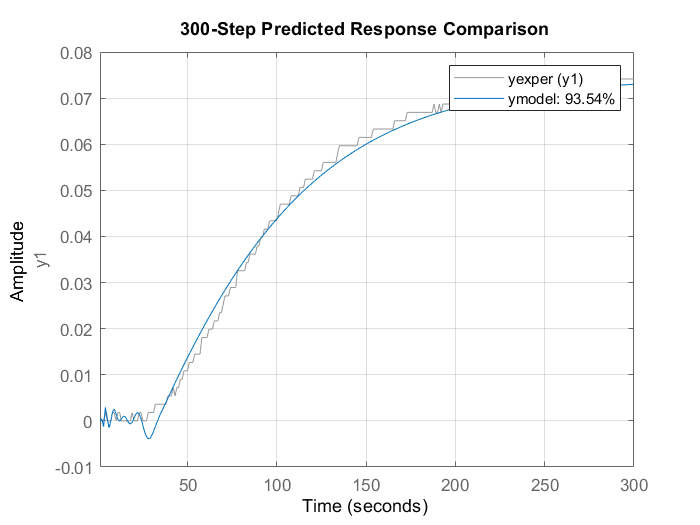

T2 = T1;

wej = [T1 T2 tau 3];
kup2rz(wej);

## Metoda Strejca

### Czujnik 1

plot(czas,y1)
title("Przebieg czasowy sygnału z czujnika 1")
xlabel("czas[s]")
ylabel("y_1(t)")
grid

line([10 50],[0 0.8],'Color','black','LineStyle','--')
line([0 300],[0.72 0.72],'Color','black','LineStyle','--')
line([45 45],[0 0.8],'Color','black','LineStyle','--')


T1 = 45;
Tm = 10;
Tz = T1 - Tm

Tz = 35

stos = Tm/Tz;
n = 3;
ti = 25;
T = ti/2

T = 12.5000

tau =(0.286 - 0.218) * 35

tau = 2.3800

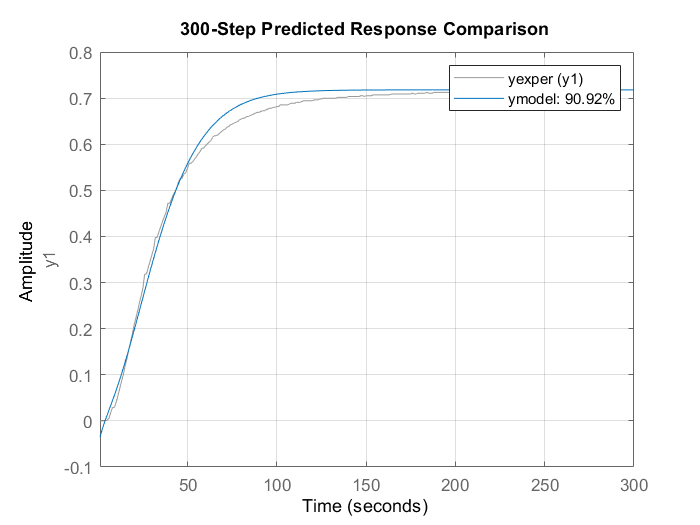

wej = [T n 1];
strejc(wej);

### Czujnik 2

plot(czas,y2)
title("Przebieg czasowy sygnału z czujnika 2")
xlabel("czas[s]")
ylabel("y_2(t)")
grid

k = max(y2)

k = 0.2586

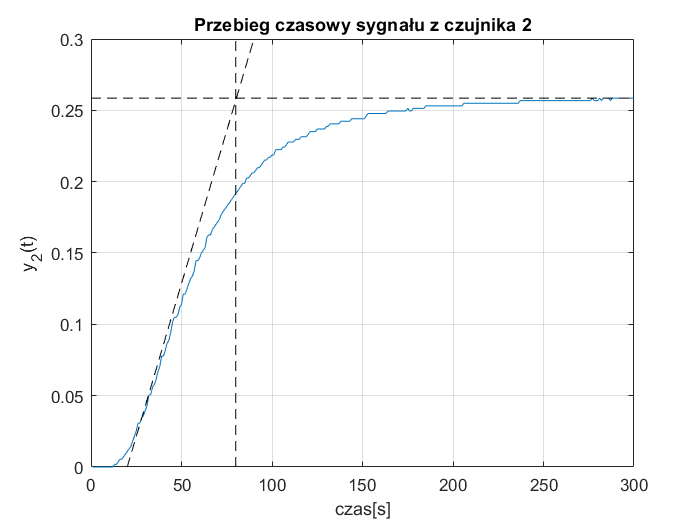


line([20 90],[0 0.3],'Color','black','LineStyle','--')
line([0 300],[k k],'Color','black','LineStyle','--')
line([80 80],[0 0.3],'Color','black','LineStyle','--')



T1 = 80;
Tm = 20;
Tz = T1 - Tm

Tz = 60

stos = Tm/Tz;
n = 4;
ti = 40;
T = ti/3

T = 13.3333

tau =(0.33 - 0.319)*60

tau = 0.6600

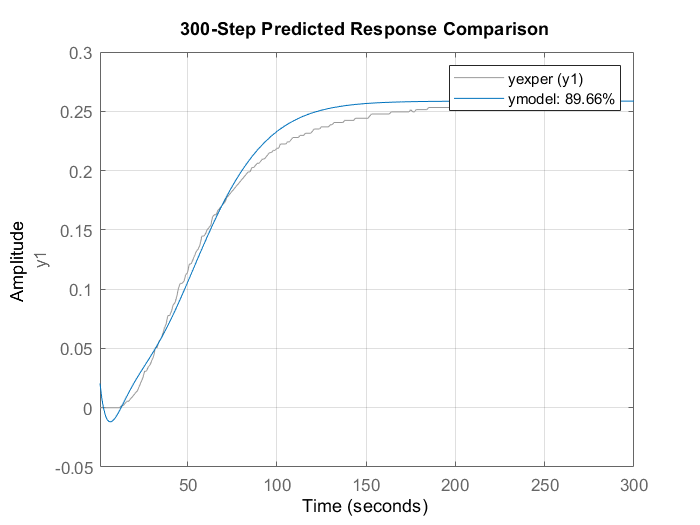

ans = 0.0576

wej = [T n 2];
strejc(wej)

### Czujnik 3

plot(czas,y3)
title("Przebieg czasowy sygnału z czujnika 3")
xlabel("czas[s]")
ylabel("y_3(t)")
grid

k = max(y3)

k = 0.0741

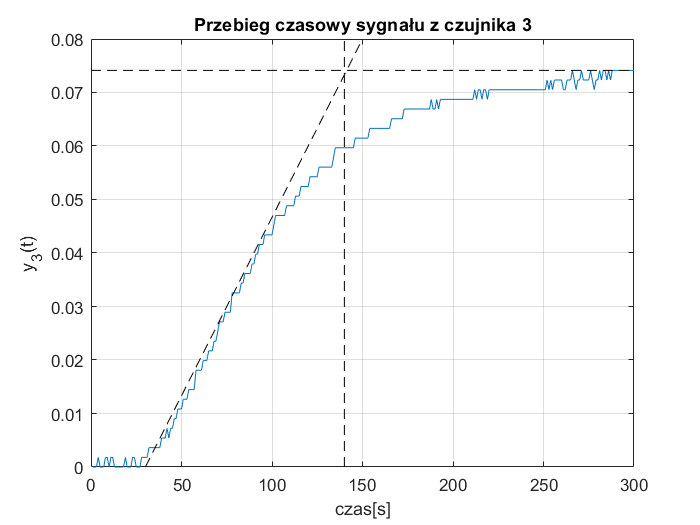


line([30 150],[0 0.08],'Color','black','LineStyle','--')
line([0 300],[k k],'Color','black','LineStyle','--')
line([140 140],[0 0.08],'Color','black','LineStyle','--')



T1 = 140;
Tm = 30;
Tz = T1 - Tm

Tz = 110

stos = Tm/Tz

stos = 0.2727

n = 3;
ti = 50;
T = ti/2

T = 25

tau = (0.273 - 0.218)*110

tau = 6.0500

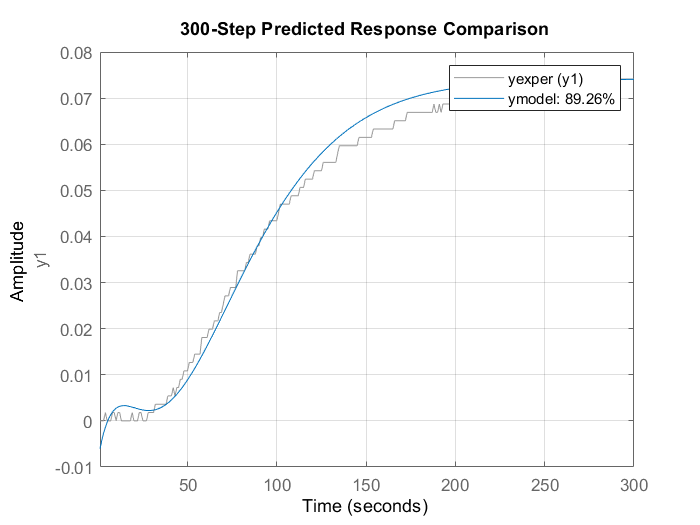

ans = 0.0194

wej = [T n 3];
strejc(wej)

### Funkcje uzyte w ćwiczeniu:

function [MSE] = kup1rz(wej)

load pomiary_3out.mat;

T = wej(1);
tau = wej(2);
nrpom = wej(3);
y = pomiary_3out(:,nrpom) - pomiary_3out(1,nrpom);
k = (y(300,1)-y(1,1))/1.0;
[ld, md] = pade(tau,10);
[l, m] = series([k],[T 1],ld,md);
czas = 1:1:300;
ym = step(l,m,czas);
MSE = sum((y-ym).^2);

plot(czas,y,czas,ym);
u = ones(size(y));
yexper = iddata(y,u,1);
ymodel = tf(l,m);
compare(yexper,ymodel,300);
grid;
end


function[MSE] = strejca(wej)

load pomiary_3out.mat;

syms s;
T = wej(1);
n = wej(2);
nrpom = wej(3);
y = pomiary_3out(:,nrpom)-pomiary_3out(1,nrpom);
k = (y(300,1)-y(1,1))/1.0;
czas = 1:1:300;
l = [k];
m = sym2poly((T*s+1).^n);
ym = step(l,m,czas);
MSE = sum((y-ym).^2);

plot(czas,y,czas,ym);
u = ones(size(y));
yexper = iddata(y,u,1);
ymodel = tf(l,m);
compare(yexper,ymodel,300);
grid;
end

## Wnioski

Dla każdego przebiegu czasowego najlepiej dopasowuje sie metoda Kumpfmullera drugiego rzędu na poziomie ok. 95% . Metody Strejca i Kupfmullera pierwszego rzędu dopasowują sie do przebiegu z dokładnością około 90%.